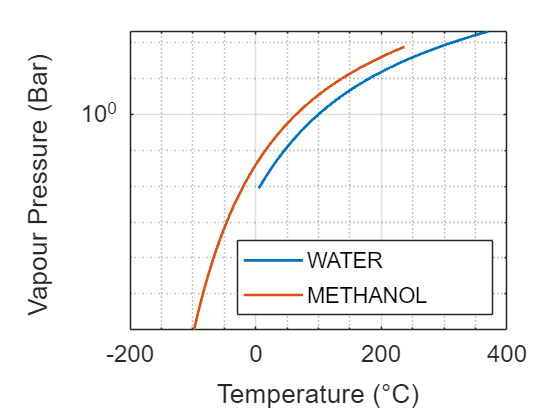

x5 = 1;


Figure = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],...
    'OuterPosition',[31 137 1128 914]);
% Create axes
axes1 = axes('Parent',Figure);
hold(axes1,'on');
for x5 = 1:n
plot1 = plot(Tx(:,x5),Pvx(:,x5),'Parent',axes1,'LineWidth',2);
set(plot1(1),'DisplayName',string(NAME(x5)));
x5 = x5+1;
end
%set(plot1(1),'DisplayName','');

% Create ylabel
ylabel({'Vapour Pressure (Bar) '});

% Create xlabel
xlabel({'Temperature (°C)'});

box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on','YScale','log');
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','southeast');